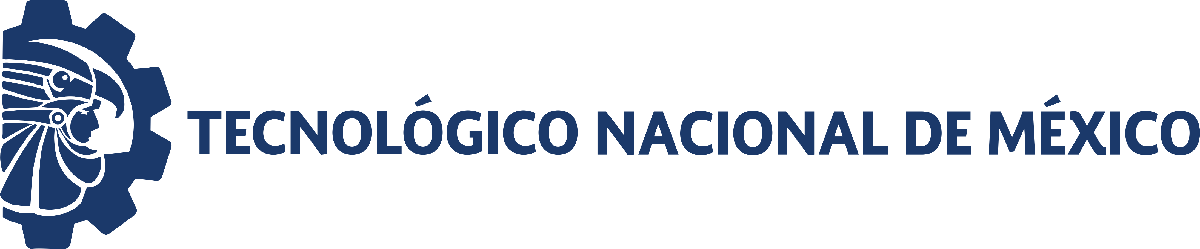                                 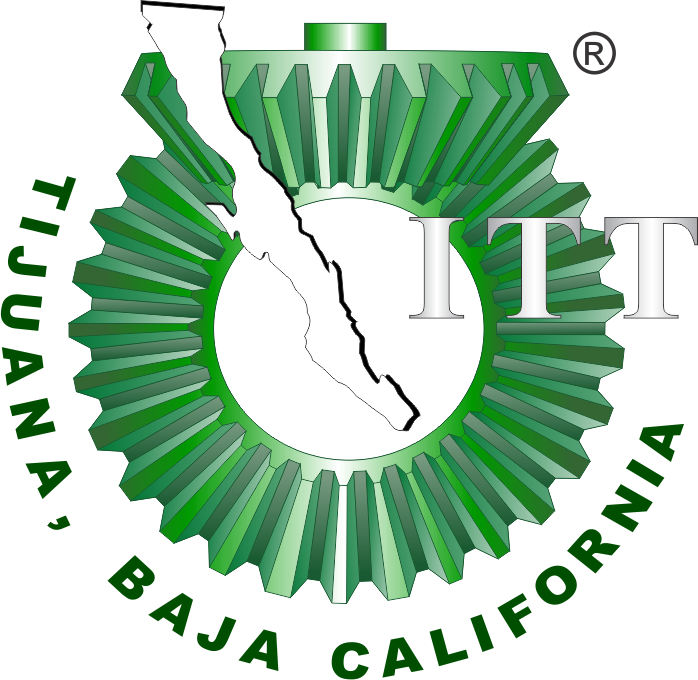

# PRACTICA 2: SISTEMA RESPIRATORIO

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[  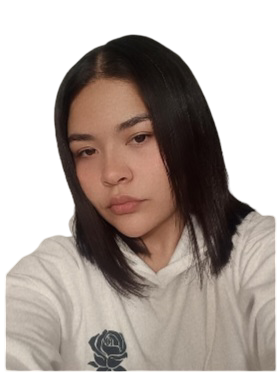  ]

Nombre del alumno: **Zamora Chon Michelle Ariadna**

Número de control: **22210432**

Correo institucional: **l22210432@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '30';
file = 'Zamora22210432P2';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

## Rendimiento del controlador

kP = 177.954;
kl = 4222.043;
kD = 0.951;
Settlingtime = '0.0003';
overshot = '0.312' ;
peak = '1';

## Respiracion Normal

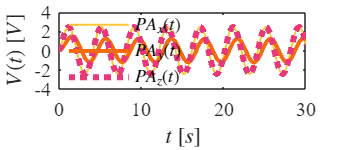

Signal = 'RESPIRACION NORMAL';
set_param('Zamora22210432P2/Pao(t)','sw','1');
set_param('Zamora22210432P2/PID Controller','P','177.954');
set_param('Zamora22210432P2/PID Controller','I','4222.043');
set_param('Zamora22210432P2/PID Controller','D','0.951');
N = sim(file,parameters);
graficarsenales(N.t, N.PAx, N.PAy, N.PAz, Signal)

## Respiracion Anormal

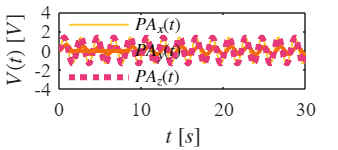

Signal = 'RESPIRACION ANORMAL';
set_param('Zamora22210432P2/Pao(t)','sw','0');
set_param('Zamora22210432P2/PID Controller','P','177.954');
set_param('Zamora22210432P2/PID Controller','I','4222.043');
set_param('Zamora22210432P2/PID Controller','D','0.951');
N = sim(file,parameters);
graficarsenales(N.t, N.PAx, N.PAy, N.PAz, Signal)

## Funcion: Respuesta a las señales

function graficarsenales(t, PAx, PAy, PAz, Signal)

set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,18,8])
set(gca,'FontName','Times New Roman')
fontsize(10,'points')
hold on; grid off; box on
AMARILLO = [252/255, 199/255, 55/255];
NARANJA = [242/255, 107/255, 15/255];
ROSA = [231/255, 56/255, 121/255];
hold on; grid off; box on

plot(t,PAx,'LineWidth',1,'Color',AMARILLO)
plot(t,PAy,'LineWidth',2,'Color',NARANJA)
plot(t,PAz,':','LineWidth',3,'Color',ROSA)

xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
ylabel('$V(t)$ $[V]$', 'Interpreter', 'Latex')

R = legend('$PA_{x}(t)$','$PA_y(t)$','$PA_{z}(t)$');
set(R,'Interpreter','Latex','Location','Best','Box','Off')

if Signal == "RESPIRACION NORMAL"
xlim([0,30]);
ylim([-4,4]);
elseif Signal == "RESPIRACION ANORMAL"
xlim([0,30]);
ylim([-4,4]); 
end
exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')
end
